# IMPORTANT 

Order of stuff in `ct_labels` is different from `valid_unit_labels`

 
data_p = fullfile( eisg.util.project_path, 'processed_data');

validity_filter = {'valid-unit', 'maybe-valid-unit'};

spike_data_filename = 'spike_data_celltype_labelled.mat';
load( fullfile( data_p, spike_data_filename ) );
valid_unit_inds = find( unit_labels, validity_filter );

% extract the spiketimes of valid units
valid_unit_spike_ts = all_unit_spike_ts( valid_unit_inds, : );
valid_unit_wfs = all_unit_wfs( valid_unit_inds, : );
valid_unit_labels = prune( unit_labels( valid_unit_inds ) );

% get the p2vs based on which classificaition was done
ct_filename = 'celltype-labels_region-separated-class_p2v.mat';
load( fullfile( data_p, ct_filename ) );
valid_unit_p2vs = feature_mat;

all_regions = valid_unit_labels('region');
n_regions = numel( all_regions );

subplot_grid = eisg.plot.get_subplot_grid( n_regions );

celltypes = valid_unit_labels('cell-type');
n_celltypes = numel( celltypes );
celltype_wf_colors = lines( n_celltypes );

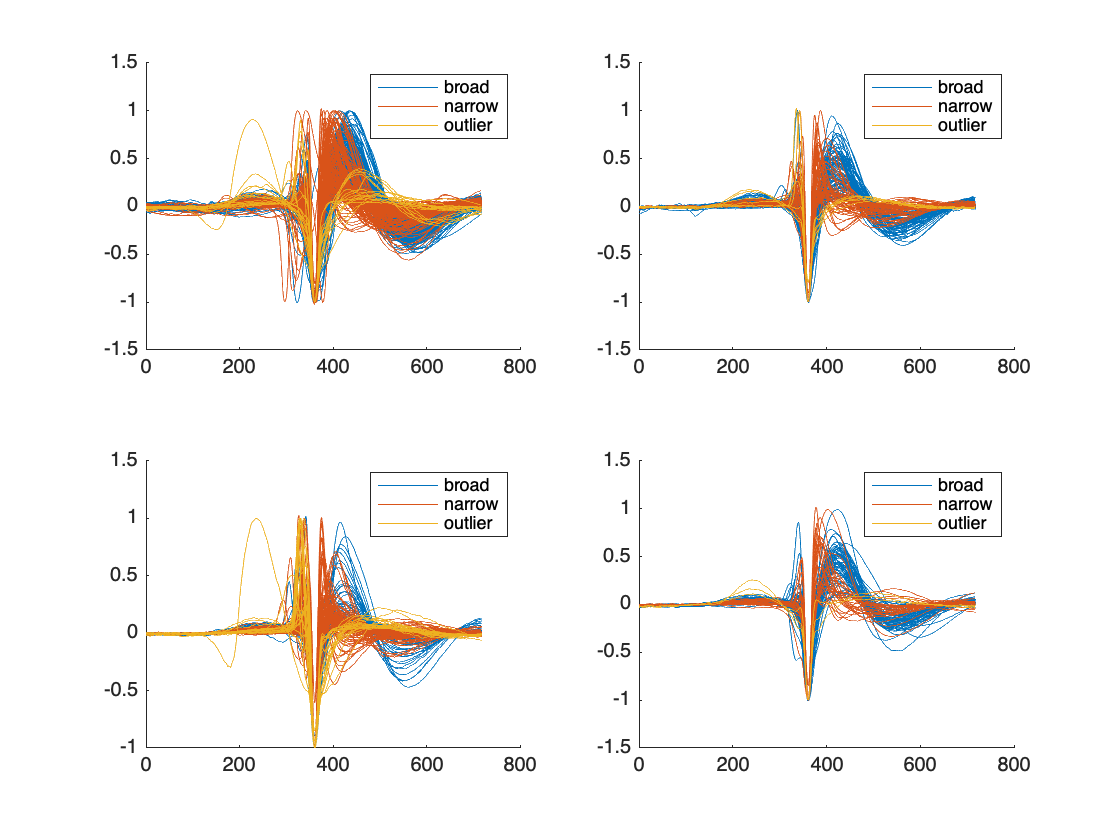

figure();
ax_wf = gobjects( n_regions, 1 );
for region_ind = 1:n_regions
    region = all_regions{ region_ind };
    ax_wf(region_ind) = subplot( subplot_grid(1), subplot_grid(2), region_ind );
    regional_unit_inds = find( valid_unit_labels, region );
    hold( ax_wf(region_ind), 'on' );
    hs = gobjects( n_celltypes, 1 );
    for celltype_ind = 1:n_celltypes
        celltype = celltypes{celltype_ind};
        celltype_unit_inds_in_region = find( valid_unit_labels, celltype, regional_unit_inds );
        wfs_to_draw = valid_unit_wfs(celltype_unit_inds_in_region, :);
        wfs_to_draw = wfs_to_draw';
        hs(celltype_ind) = plot( ax_wf(region_ind), wfs_to_draw(:,1), ...
            'Color', celltype_wf_colors(celltype_ind, :), ...
            'DisplayName', celltype);
        plot( ax_wf(region_ind), wfs_to_draw(:,2:end), ...
            'Color', celltype_wf_colors(celltype_ind, :));
    end
    hold( ax_wf(region_ind), 'off' );
    legend( hs );
end

Hello!

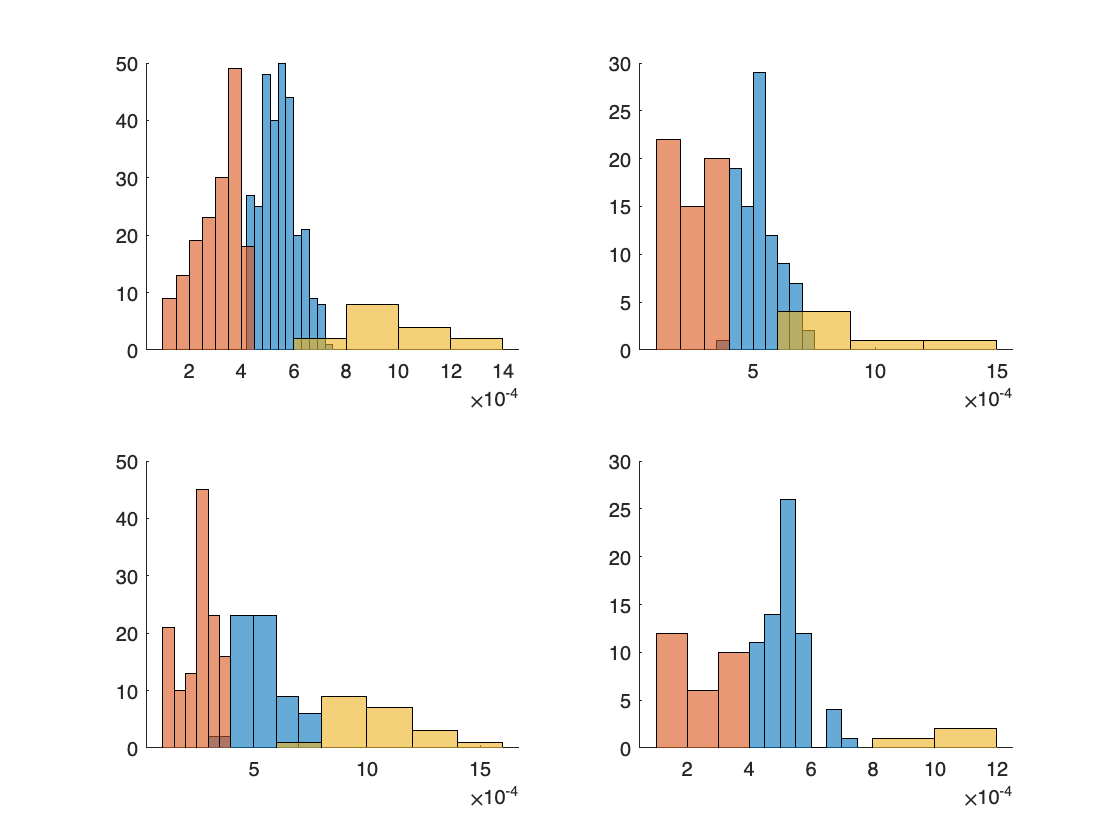

[uuid_I, uuids] = findall( valid_unit_labels, 'uuid' );
match_I = bfw.find_combinations( ct_labels, uuids );
valid_unit_p2vs = nan( size( feature_mat ) );
for i = 1:numel(uuid_I)
    if (~isempty(match_I{i}))
        valid_unit_p2vs(i) = feature_mat(match_I{i});
    end
end


figure();
ax_p2v = gobjects( n_regions, 1 );
for region_ind = 1:n_regions
    region = all_regions{ region_ind };
    ax_p2v(region_ind) = subplot( subplot_grid(1), subplot_grid(2), region_ind );
    regional_unit_inds = find( valid_unit_labels, region );
    hold( ax_p2v(region_ind), 'on' );
    for celltype_ind = 1:n_celltypes
        celltype = celltypes{celltype_ind};
        celltype_unit_inds_in_region = find( valid_unit_labels, celltype, regional_unit_inds );
        p2vs_to_draw = valid_unit_p2vs(celltype_unit_inds_in_region, :);
        histogram( ax_p2v(region_ind), p2vs_to_draw, ...
            'FaceColor', celltype_wf_colors(celltype_ind, :) );
    end
    hold( ax_p2v(region_ind), 'off' );
end